# **Assignment:  Feature Extraction of CWRU Dataset**

**Name: Gyeonheal An**

**ID: 21900416**

## **Contents**

- `Extract Time-Domain Features`

- `Extract Freq-Domain Features`

- `Envelope Extraction`

- `STFT`

- `Kurtogram`

- `Apply Bandpass filter & Spectral Kurtosis`

- `Discussion : Feature Analysis and Comparison  `

- `Conclusion`

## **Instruction**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of Feature Extration in  the literature 

[Download here](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Docs)

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Extract and Analyze  Features**

**3. Compare  Features among different classes**

**Other reference**

Diagnostics 101: A Tutorial for Fault Diagnostics of Rolling Element Bearing Using Envelope Analysis in MATLAB 

[Matlab code]: [https://www.kau-sdol.com/matlab-code](https://www.kau-sdol.com/matlab-code)

## Dataset

**A sample of selected  CWRU bearing dataset **

- 1 data file for each fault state under specific condition

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Raw_data.zip**  

- `/Dataset/CWRU_selected_dataset/Raw_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Raw_data/`

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

## 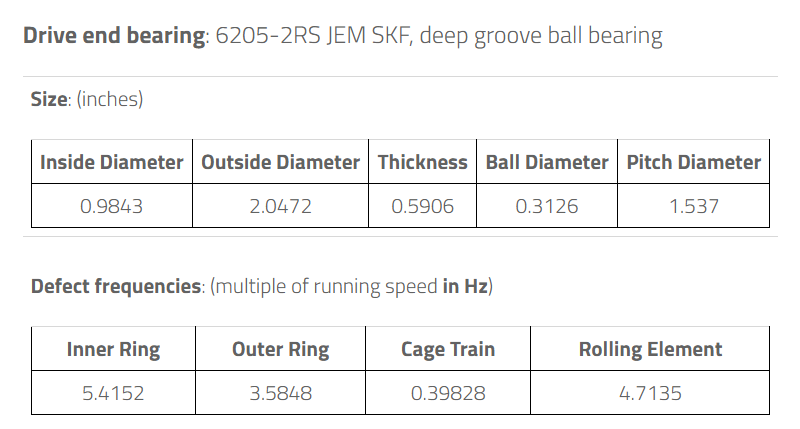

## Introduction

Analytical Signal in Frequency-Domain approach, using Envelope Extraction

addpath('../../Library')

## Load Dataset

close all; clear; clc;

addpath("../../Dataset/CWRU_selected_dataset/Raw_data")


load('ball_007_1hp.mat') %X119
load('inner_007_1hp.mat') %X106
load('normal_1hp.mat') %X098
load('outer_007_1hp.mat') %X131

## **Preprocessing**

- Ballpass frequency, outer race (BPFO)


$$BPFO = \frac{nf_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ballpass frequency, inner race (BPFI)


$$BPFI = \frac{nf_r}{2}\left(1+\frac{d}{D}\cos \phi\right)$$


- Fundamental train frequency (FTF), also known as cage speed


$$FTF = \frac{f_r}{2}\left(1-\frac{d}{D}\cos \phi\right)$$


- Ball (roller) spin frequency


$$BSF = \frac{D}{2d}\left[1-\left(\frac{d}{D}\cos \phi\right)^2\right]$$


%%% YOUR CODE GOES HERE
fs = 12000;

fr_inner = X106RPM*(2*pi)/60.0;
fr_outer = X131RPM*(2*pi)/60.0;

BPFO_freq = 3.5848 * X131RPM / 60;
BPFI_freq = 5.4152 * X106RPM / 60;
BPFB_freq = 4.7135 * X119RPM / 60;

L_BALL = length(X119_DE_time);
L_INNER = length(X106_DE_time);
L_NORMAL = length(X098_DE_time);
L_OUTER = length(X131_DE_time);

## **Features Extraction**

• Extract Time-Domain Features

- Mean, Std, Skewness, Kurtosis, Peak2Peak, RMS, CrestFactor,  ShapeFactor, ImpulseFactor, MarginFactor, Energy etc

• Extract Frequency-Domain Features

-   Basic features,  SKMean, SKStd, SKSkewness, SKKurtosis, etc

• Envelope Extraction

• Plot  STFT 

• Plot  Kurtogram

• Analyze Spectral Kurtosis

## **1. Extract Time-Domain Features**

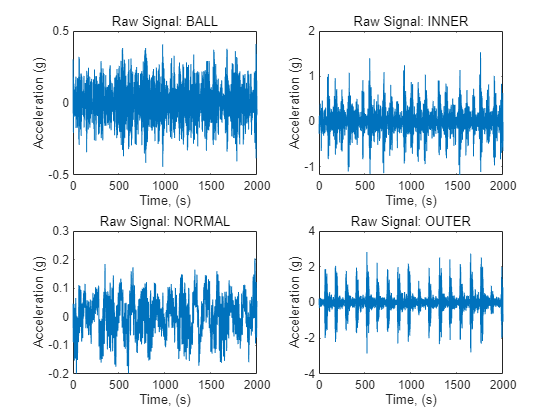

figure
subplot(2, 2, 1);
plot(X119_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: BALL');
hold on;

subplot(2,2,2);
plot(X106_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: INNER');

hold on;
subplot(2,2,3);
plot(X098_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: NORMAL');

hold on;
subplot(2,2,4);
plot(X131_DE_time(1:2000));
xlabel('Time, (s)');
ylabel('Acceleration (g)');
title('Raw Signal: OUTER');

ball_time_features = timeFeatures(X119_DE_time) % Ball timeFeatures

ball_time_features = 1×14 table
      mean         std        rms        sra         aav      energy     peak       ppv        if        sf        cf        mf         sk          kt  
    _________    _______    _______    ________    _______    ______    _______    ______    ______    ______    ______    ______    _________    ______

    0.0038918    0.13901    0.13907    0.094363    0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638


inner_time_features = timeFeatures(X106_DE_time) % Inner timeFeatures

inner_time_features = 1×14 table
      mean        std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf        sk         kt  
    ________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    _______    ______

    0.005801    0.29284    0.29289    0.16484    0.20764    10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902    0.13043    5.5423


normal_time_features = timeFeatures(X098_DE_time) % Normal timeFeatures

normal_time_features = 1×14 table
      mean        std         rms         sra         aav       energy     peak       ppv        if        sf        cf       mf         sk         kt  
    ________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    _____    ________    ______

    0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129    7.594    -0.17305    2.9306


outer_time_features = timeFeatures(X131_DE_time) % Outer timeFeatures

outer_time_features = 1×14 table
      mean         std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk        kt  
    _________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ________    _____

    0.0040611    0.59194    0.59195    0.26626    0.36646    42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689    0.033401    7.595


## 2. Extract Frequency-Domain Features

T_BALL = (0:L_BALL) / fs;
T_INNER = (0:L_INNER) / fs;
T_NORMAL = (0:L_NORMAL) / fs;
T_OUTER = (0:L_OUTER) / fs;

fft_BALL = getFFT(X119_DE_time, L_BALL);
fft_INNER = getFFT(X106_DE_time, L_INNER);

fft_NORMAL = getFFT(X098_DE_time, L_NORMAL);

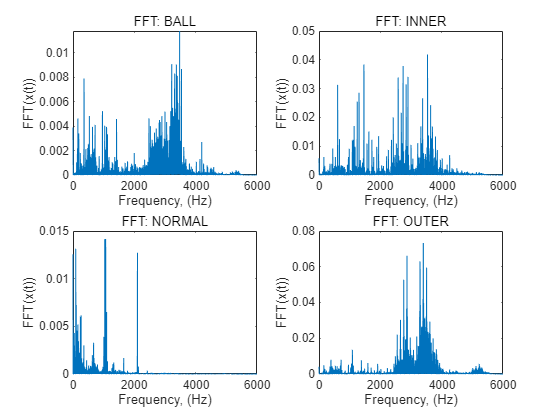

fft_OUTER = getFFT(X131_DE_time, L_OUTER);

f_BALL = 0:fs/L_BALL:fs/2;
f_INNER = 0:fs/L_INNER:fs/2;
f_NORMAL = 0:fs/L_NORMAL:fs/2;
f_OUTER = 0:fs/L_OUTER:fs/2;

figure
subplot(2, 2, 1);
plot(f_BALL, fft_BALL);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: BALL');
hold on;

subplot(2,2,2);
plot(f_INNER, fft_INNER);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: INNER');

hold on;
subplot(2,2,3);
plot(f_NORMAL, fft_NORMAL);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: NORMAL');

hold on;
subplot(2,2,4);
plot(f_OUTER, fft_OUTER);
xlabel('Frequency, (Hz)');
ylabel('FFT(x(t))');
title('FFT: OUTER');

ball_freq_features = freqFeatures(fft_BALL)

ball_freq_features = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00013212    0.00039927    0.00037678


inner_freq_features = freqFeatures(fft_INNER)

inner_freq_features = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00025571    0.00083874    0.00079881


normal_freq_features = freqFeatures(fft_NORMAL)

normal_freq_features = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    2.0723e-05    9.7079e-05    9.4841e-05


outer_freq_features = freqFeatures(fft_OUTER)

outer_freq_features = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00041833    0.0016918    0.0016393


## 3. Envelop Extraction

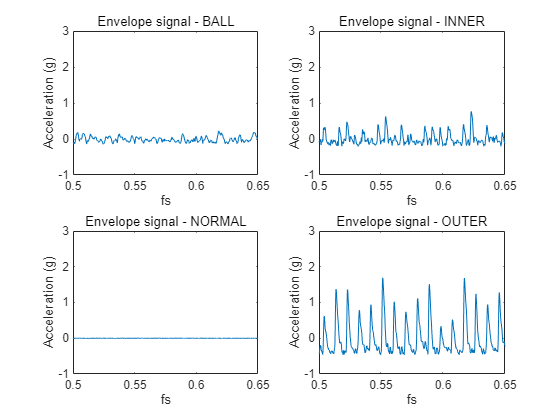

figure;

[pEnvBALL, fEnvBALL, xEnvBALL, tEnvBALL] = envspectrum(X119_DE_time, fs);
subplot(2, 2, 1);
plot(tEnvBALL, xEnvBALL);
xlim([0.5 0.65]);
ylim([-1 3]);
xlabel('fs')
ylabel('Acceleration (g)')
title('Envelope signal - BALL')

hold on;
[pEnvINNER, fEnvINNER, xEnvINNER, tEnvINNER] = envspectrum(X106_DE_time, fs);
subplot(2, 2, 2);
plot(tEnvINNER, xEnvINNER);
xlim([0.5 0.65]);
ylim([-1 3]);
xlabel('fs')
ylabel('Acceleration (g)')
title('Envelope signal - INNER')

hold on;
[pEnvNORMAL, fEnvNORMAL, xEnvNORMAL, tEnvNORMAL] = envspectrum(X098_DE_time, fs);
subplot(2, 2, 3);
plot(tEnvNORMAL, xEnvNORMAL);
xlim([0.5 0.65]);
ylim([-1 3]);
xlabel('fs')
ylabel('Acceleration (g)')
title('Envelope signal - NORMAL')

hold on;
[pEnvOUTER, fEnvOUTER, xEnvOUTER, tEnvOUTER] = envspectrum(X131_DE_time, fs);
subplot(2, 2, 4);
plot(tEnvOUTER, xEnvOUTER);
xlim([0.5 0.65]);
ylim([-1 3]);
xlabel('fs')
ylabel('Acceleration (g)')
title('Envelope signal - OUTER')

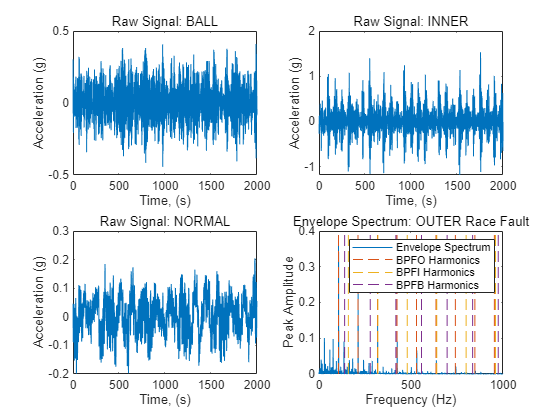

figure(1);
plot(fEnvBALL, pEnvBALL)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: BALL Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')
plot(fEnvINNER, pEnvINNER)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: INNER Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')
plot(fEnvNORMAL, pEnvNORMAL)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: NORMAL Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')
plot(fEnvOUTER, pEnvOUTER)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: OUTER Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics', 'BPFB Harmonics')

## 4. STFT

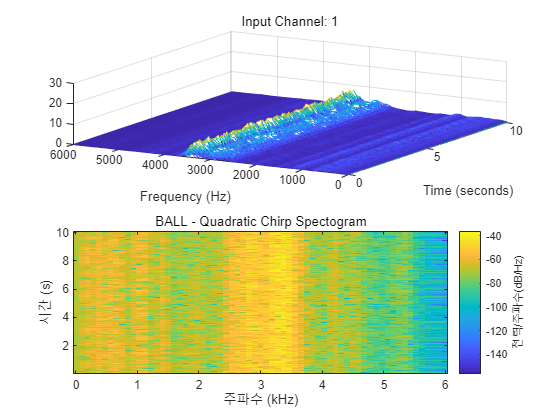

figure;
subplot(2,1,1);
[S,F,T] = stft(X119_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(1)
hold on;
subplot(2,1,2);
spectrogram(X119_DE_time,128,50,128, fs)
title('BALL - Quadratic Chirp Spectogram')

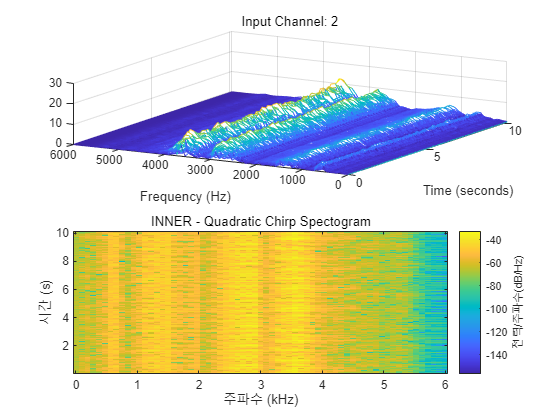

figure;
subplot(2,1,1);
[S,F,T] = stft(X106_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(2)
hold on;
subplot(2,1,2);
spectrogram(X106_DE_time,128,50,128, fs)
title('INNER - Quadratic Chirp Spectogram')

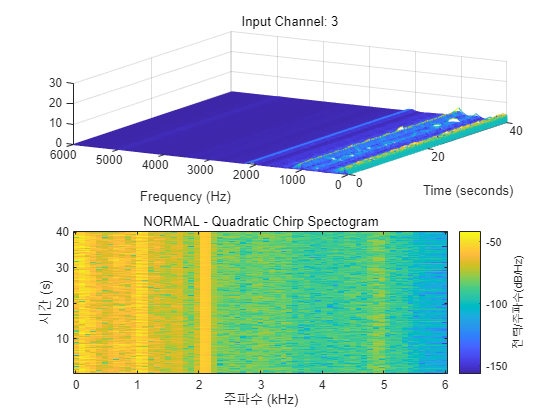

figure;
subplot(2,1,1);
[S,F,T] = stft(X098_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(3)
hold on;
subplot(2,1,2);
spectrogram(X098_DE_time,128,50,128, fs)
title('NORMAL - Quadratic Chirp Spectogram')

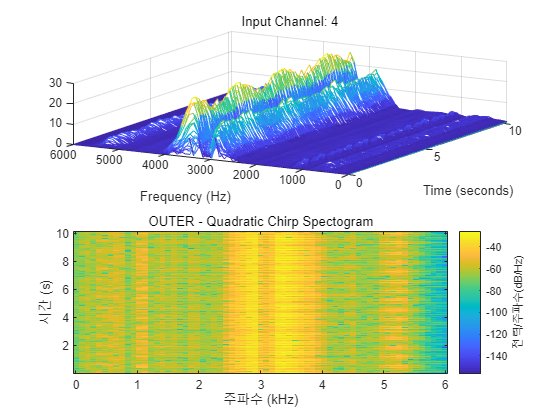

figure;
subplot(2,1,1);
[S,F,T] = stft(X131_DE_time,fs,Window=kaiser(128,5),OverlapLength=50,FFTLength=128, FrequencyRange = 'onesided');
waterfall(F,T,abs(S)')
helperGraphicsOpt(4)
hold on;
subplot(2,1,2);
spectrogram(X131_DE_time,128,50,128, fs)
title('OUTER - Quadratic Chirp Spectogram')

function helperGraphicsOpt(ChannelId)
ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 30];
ax.Title.String = ['Input Channel: ' num2str(ChannelId)];
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Time (seconds)';
ax.View = [30 45];
end

## 5. Kurtogram

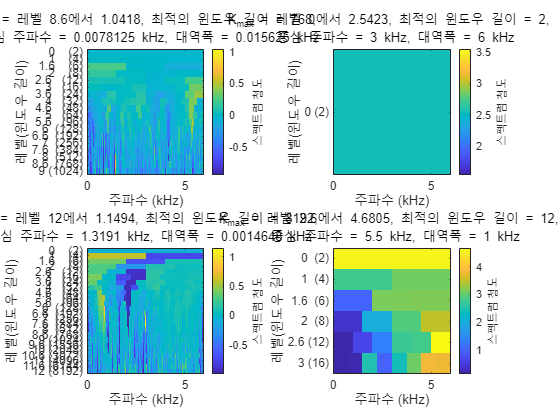

lv_BALL = 9; lv_INNER = 0; lv_NORMAL = 12; lv_OUTER = 3;

figure;
subplot(2,2,1);
kurtogram(X119_DE_time, fs, lv_BALL);

hold on;
subplot(2,2,2);
kurtogram(X106_DE_time, fs, lv_INNER);

hold on;
subplot(2,2,3);
kurtogram(X098_DE_time, fs, lv_NORMAL);

hold on;
subplot(2,2,4);
kurtogram(X131_DE_time, fs, lv_OUTER);

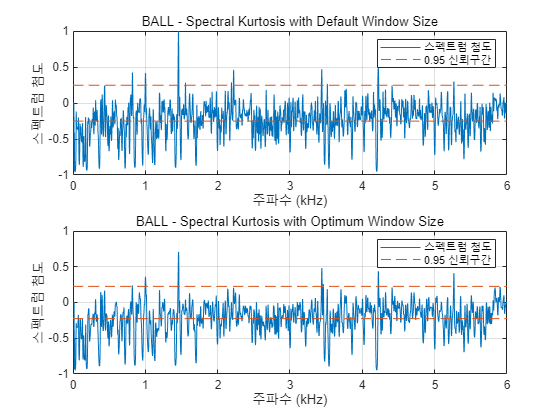

figure;
subplot(2,1,1);
pkurtosis(X119_DE_time, fs);
title('BALL - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_BALL,f_BALL,w_BALL,fc_BALL,wc_BALL,bw_BALL] = kurtogram(X119_DE_time, fs, lv_BALL);
pkurtosis(X119_DE_time,fs, wc_BALL)
title('BALL - Spectral Kurtosis with Optimum Window Size')

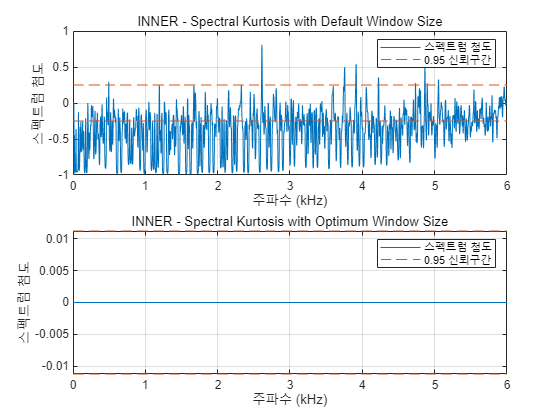

figure;
subplot(2,1,1);
pkurtosis(X106_DE_time, fs);
title('INNER - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_INNER,f_INNER,w_INNER,fc_INNER,wc_INNER,bw_INNER] = kurtogram(X106_DE_time, fs, lv_INNER);
pkurtosis(X106_DE_time,fs, wc_INNER)
title('INNER - Spectral Kurtosis with Optimum Window Size')

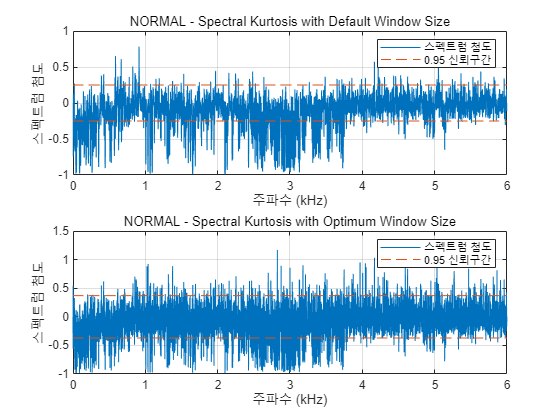

figure;
subplot(2,1,1);
pkurtosis(X098_DE_time, fs);
title('NORMAL - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_NORMAL,f_NORMAL,w_NORMAL,fc_NORMAL,wc_NORMAL,bw_NORMAL] = kurtogram(X098_DE_time, fs, lv_NORMAL);
pkurtosis(X098_DE_time,fs, wc_NORMAL)
title('NORMAL - Spectral Kurtosis with Optimum Window Size')

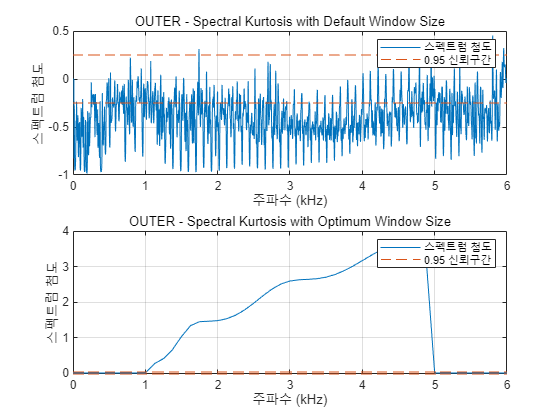

figure;
subplot(2,1,1);
pkurtosis(X131_DE_time, fs);
title('OUTER - Spectral Kurtosis with Default Window Size')
hold on;
subplot(2,1,2);
[kgram_OUTER,f_OUTER,w_OUTER,fc_OUTER,wc_OUTER,bw_OUTER] = kurtogram(X131_DE_time, fs, lv_OUTER);
pkurtosis(X131_DE_time,fs, wc_OUTER)
title('OUTER - Spectral Kurtosis with Optimum Window Size')

## **6. Apply Bandpass filter & Spectral Kurtosis**

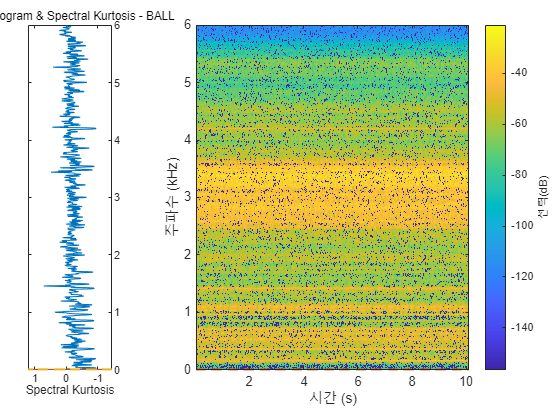

figure;
helperSpectrogramAndSpectralKurtosis(X119_DE_time, fs, lv_BALL)
title('Spectrogram & Spectral Kurtosis - BALL');

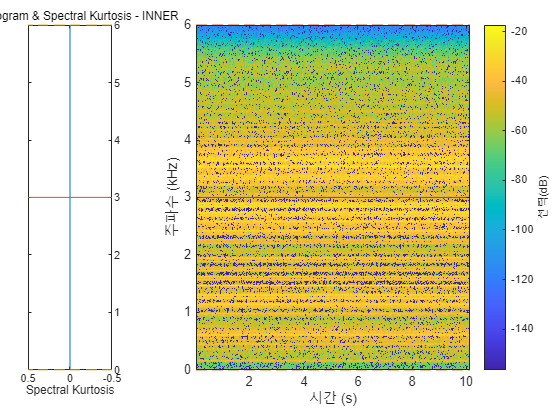

helperSpectrogramAndSpectralKurtosis(X106_DE_time, fs, lv_INNER)
title('Spectrogram & Spectral Kurtosis - INNER');

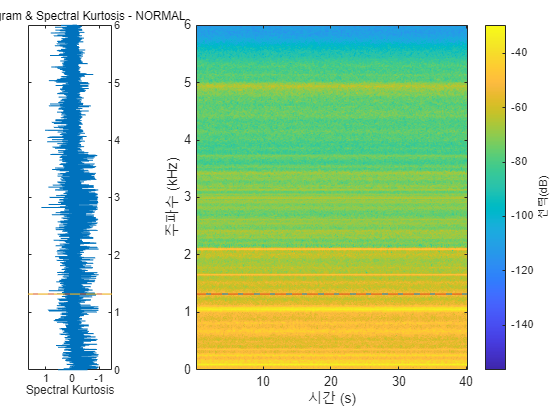

helperSpectrogramAndSpectralKurtosis(X098_DE_time, fs, lv_NORMAL)
title('Spectrogram & Spectral Kurtosis - NORMAL');

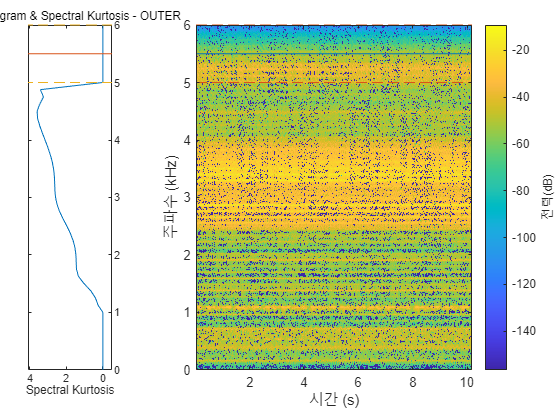

helperSpectrogramAndSpectralKurtosis(X131_DE_time, fs, lv_OUTER)
title('Spectrogram & Spectral Kurtosis - OUTER');

xNormal = X098_DE_time;
xBall = X119_DE_time;
xInner = X106_DE_time;
xOuter = X131_DE_time;

#### 6-1. Ball fault bandpass filter applying

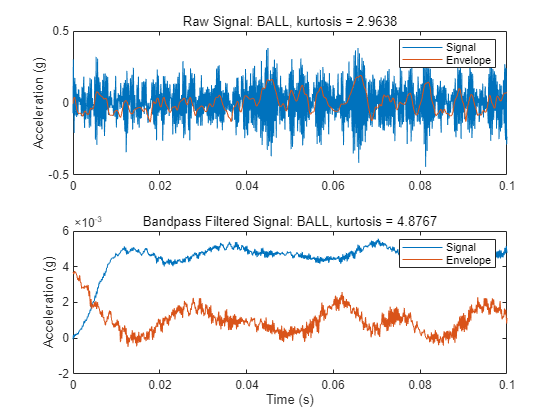

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_BALL-bw_BALL/2 + 1, ...
    'CutoffFrequency2', fc_BALL + bw_BALL/2 - 1, 'SampleRate', fs);

% Apply bandpass filter
xBALLBpf = filter(bpf, xBall);

% Calculate Kurtosis
kurtBALL = kurtosis(xBall);
kurtBALLBpf = kurtosis(xBALLBpf);

% Apply bandpass filtered envelope spectrum
[pEnvBALLBpf, fEnvBALLBpf, xEnvBALLBpf, tEnvBpfBALL] = envspectrum(xBall, fs, ...
    'FilterOrder', 200, 'Band', [(fc_BALL-bw_BALL/2)/fs (fc_BALL+bw_BALL/2)/fs]);

figure
subplot(2, 1, 1)
plot(T_BALL(1:121410), xBall, tEnvBALL, xEnvBALL)
ylabel('Acceleration (g)')
title(['Raw Signal: BALL, kurtosis = ', num2str(kurtBALL)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_BALL(1:121410), xBALLBpf, tEnvBpfBALL, xEnvBALLBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: BALL, kurtosis = ', num2str(kurtBALLBpf)])
legend('Signal', 'Envelope')

#### 6-2. Inner race fault bandpass filter applying

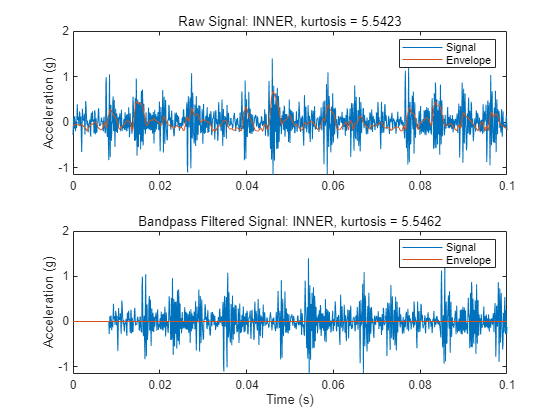

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', (fc_INNER - bw_INNER/2 + 1), ...
    'CutoffFrequency2', (fc_INNER + bw_INNER/2 - 1), 'SampleRate', fs);

% Apply bandpass filter
xINNERBpf = filter(bpf, xInner);

% Calculate Kurtosis
kurtINNER = kurtosis(xInner);
kurtINNERBpf = kurtosis(xINNERBpf);

% Apply bandpass filtered envelope spectrum
[pEnvINNERBpf, fEnvINNERBpf, xEnvINNERBpf, tEnvBpfINNER] = envspectrum(xInner, fs, ...
    'FilterOrder', 200, 'Band', [(fc_INNER-bw_INNER/2)/fs (fc_INNER+bw_INNER/2)/fs]);

figure;
subplot(2, 1, 1)
plot(T_INNER(1:121991), xInner, tEnvINNER, xEnvINNER)
ylabel('Acceleration (g)')
title(['Raw Signal: INNER, kurtosis = ', num2str(kurtINNER)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_INNER(1:121991), xINNERBpf, tEnvBpfINNER, xEnvINNERBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: INNER, kurtosis = ', num2str(kurtINNERBpf)])
legend('Signal', 'Envelope')

#### 6-3. Normal fault bandpass filter applying

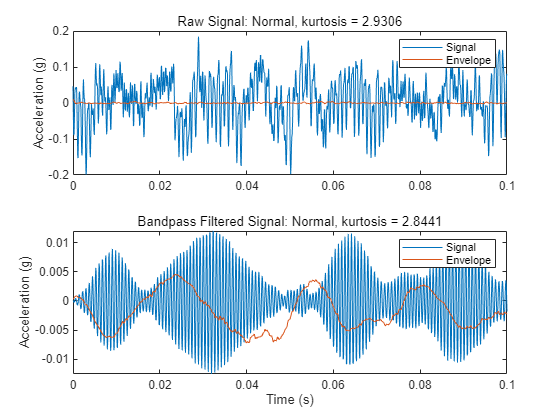

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_NORMAL-bw_NORMAL/2, ...
    'CutoffFrequency2', fc_NORMAL+bw_NORMAL/2, 'SampleRate', fs);

% Apply bandpass filter
xNORMALBpf = filter(bpf, xNormal);

% Calculate Kurtosis
kurtNORMAL = kurtosis(xNormal);
kurtNORMALBpf = kurtosis(xNORMALBpf);

% Apply bandpass filtered envelope spectrum
[pEnvNORMALBpf, fEnvNORMALBpf, xEnvNORMALBpf, tEnvBpfNORMAL] = envspectrum(xNormal, fs, ...
    'FilterOrder', 200, 'Band', [fc_NORMAL-bw_NORMAL/2 fc_NORMAL+bw_NORMAL/2]);

figure;
subplot(2, 1, 1)
plot(T_NORMAL(1:483903), xNormal, tEnvNORMAL, xEnvNORMAL)
ylabel('Acceleration (g)')
title(['Raw Signal: Normal, kurtosis = ', num2str(kurtNORMAL)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_NORMAL(1:483903), xNORMALBpf, tEnvBpfNORMAL, xEnvNORMALBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Normal, kurtosis = ', num2str(kurtNORMALBpf)])
legend('Signal', 'Envelope')

#### 6-4. Outer race fault bandpass filter applying

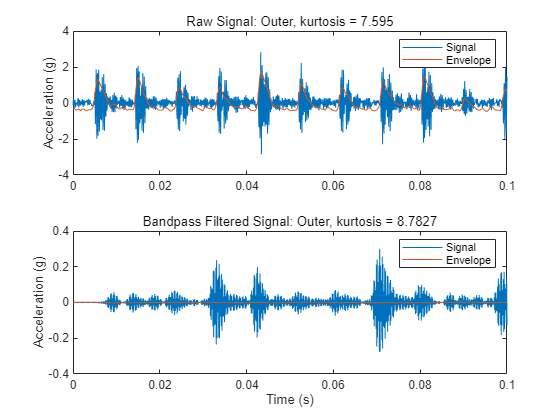

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_OUTER-bw_OUTER/2 + 1, ...
    'CutoffFrequency2', fc_OUTER+bw_OUTER/2 - 1, 'SampleRate', fs);

% Apply bandpass filter
xOUTERBpf = filter(bpf, xOuter);

% Calculate Kurtosis
kurtOUTER = kurtosis(xOuter);
kurtOUTERBpf = kurtosis(xOUTERBpf);

% Apply bandpass filtered envelope spectrum
[pEnvOUTERBpf, fEnvOUTERBpf, xEnvOUTERBpf, tEnvBpfOUTER] = envspectrum(xOuter, fs, ...
    'FilterOrder', 200, 'Band', [(fc_OUTER-bw_OUTER/2)/fs (fc_OUTER+bw_OUTER/2)/fs]);

figure;
subplot(2, 1, 1)
plot(T_OUTER(1:122426), xOuter, tEnvOUTER, xEnvOUTER)
ylabel('Acceleration (g)')
title(['Raw Signal: Outer, kurtosis = ', num2str(kurtOUTER)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(T_OUTER(1:122426), xOUTERBpf, tEnvBpfOUTER, xEnvOUTERBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Outer, kurtosis = ', num2str(kurtOUTERBpf)])
legend('Signal', 'Envelope')

## **7. Discussion : Feature Analysis and Comparison  **

### 7-1. Discussion about Time Domain Feature Extraction

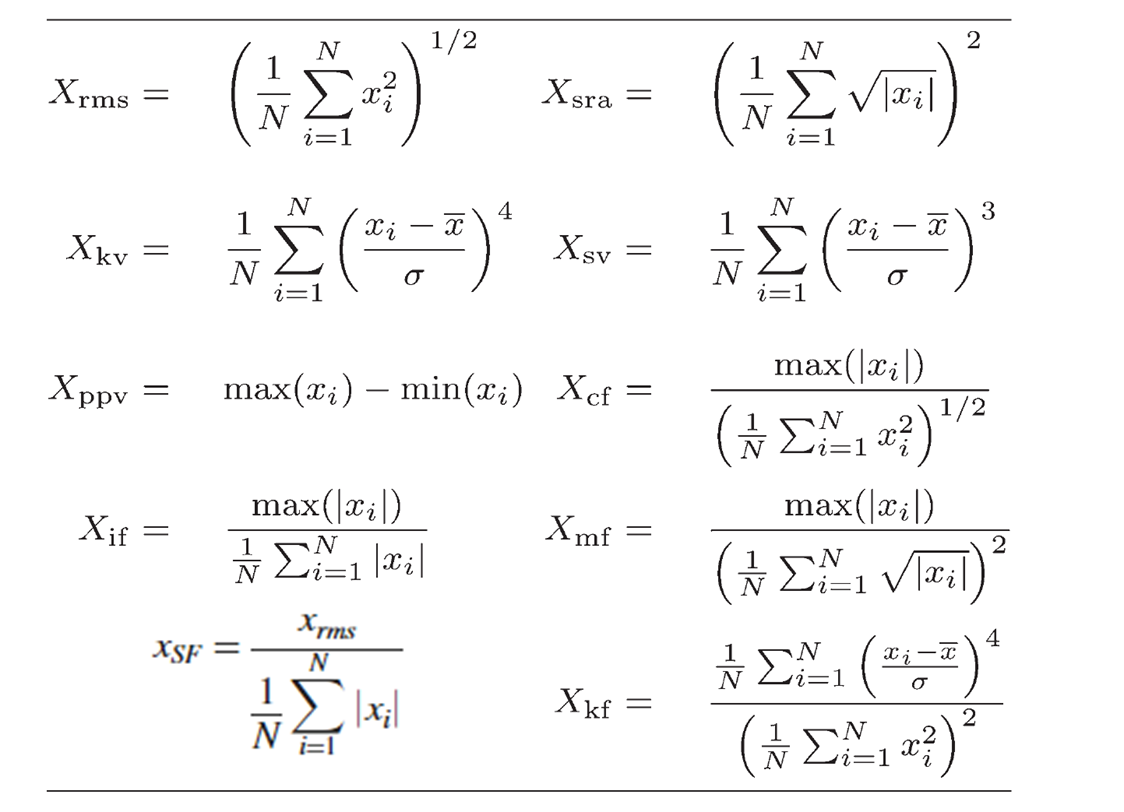

I conducted time domain feature extraction on Ball, Inner race, Outer race, and Normal data, comparing the values of Mean, Std, Skewness, Kurtosis, Peak-to-Peak, RMS, Crest Factor, Shape Factor, Impulse Factor, Margin Factor, and Energy.

As you can see the table below, sequently, Ball, Inner race, Normal, Outer race Data.

time_features = [ball_time_features; inner_time_features; normal_time_features; outer_time_features];
disp(time_features);

      mean         std         rms         sra         aav       energy     peak       ppv        if        sf        cf        mf         sk          kt  
    _________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    ______    _________    ______

    0.0038918     0.13901     0.13907    0.094363     0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638
     0.005801     0.29284     0.29289     0.16484     0.20764     10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902      0.13043    5.5423
     0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129     7.594     -0.17305    2.9306
    0.0040611     0.59194     0.59195     0.26626     0.36646     42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689     0.033401     7.595



**(1). Mean : The average value of the signal over time.**

- It indicates the overall level or central tendency of the signal, helping to determine if the system is operating normally.

- Looking at the mean values converging towards 0 for all four data sets, this feature does not seem to provide meaningful information for fault diagnosis

**(2). Standard Deviation : Measures the variability or spread of the signal around its mean.**

- It indicates the overall level or central tendency of the signal, helping to determine if the system is operating normally.

- Among the four data sets, the Outer race data has the highest value, indicating that the fluctuation range of this data is the largest. However, it is difficult to make a fault diagnosis based on this feature alone.

**(3). RMS: The square root of the mean of the squared signal values.**

- This value reflects the energy level of the signal. A higher RMS indicates a more energetic signal, often used to assess vibration or electrical signals.

- Similar to the standard deviation, the Outer race data has the highest RMS value.

**(4). SRA: Represents the square root of the signal amplitude.**

- It provides insight into the magnitude of signal fluctuations.

- The energy value of the Outer race data is the highest, suggesting that the system may be experiencing higher stress.

**(5). Energy: The total energy of the signal, calculated by summing the squared values of the signal.**

- Indicates the overall energy consumption of the system. Higher energy levels might suggest that the system is under more stress.

- As with the standard deviation, the Outer race data has the largest PPV value.

**(6). PPV: The difference between the maximum and minimum signal values.**

- It measures the total amplitude of the signal and indicates the range of fluctuation within the signal.

- As with the standard deviation, the Outer race data has the largest PPV value.

**(7): ImpulseFactor: The ratio of peak amplitude to the average amplitude.**

- Used to detect sudden shocks or abrupt changes in the signal, often related to faults or malfunctions.

- Among the four data sets, the Outer race data has the largest value, indicating that shocks or changes may have occurred.

**(8): ShapeFactor: The ratio of RMS to the average absolute value.**

- Provides information about the shape or form of the signal, helping to evaluate how irregular or uniform the signal is.

- All four data sets have similar Shape Factor values.

**(9): CrestFactor: The ratio of peak amplitude to RMS.**

- This is useful in detecting sharp peaks in the signal, often associated with transient events or system faults.

- Although the Outer race data had the largest Impulse Factor, its Crest Factor is similar to other data sets, making it difficult to diagnose faults based on this feature.

**(10): MarginFactor: The ratio of peak amplitude to the mean amplitude.**

- It helps assess the safety margin of the system, indicating how far the system operates from extreme values.

- Among the four data sets, the Outer race data has the largest value, indicating that this system has the lowest stability.

**(11): Skewness: A measure of the asymmetry of the signal distribution.**

- Positive skewness indicates the signal is skewed to the right, and negative skewness indicates it is skewed to the left. It’s useful for detecting whether the signal is balanced or biased.

- All four data sets show values close to 0, indicating that the signals are symmetric.

**(12): Kurtosis: A measure of the peakedness or "tailedness" of the signal distribution.**

- High kurtosis indicates that extreme values or outliers are more likely, which can be a sign of fault or abnormal events in the system.

- Among the four data sets, the Outer race data has the highest number of outliers.

Based on the comprehensive analysis of the time domain feature extraction results, the Outer race data shows higher standard deviation, greater energy, and more outliers compared to the other data sets, which raises suspicion of a fault. However, these features do not exhibit enough distinction to definitively diagnose an outer race fault, so further verification using other methods is required for a clear diagnosis.

### 7-2. Discussion about Frequency Domain Feature Extraction

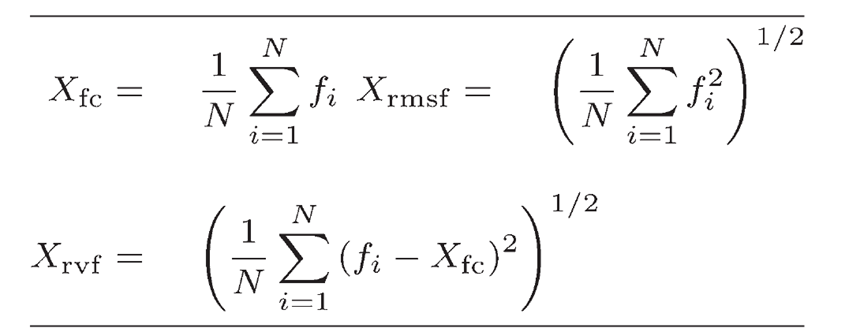

I conducted frequency domain feature extraction on Ball, Inner race, Outer race, and Normal data, comparing the values of center frequency(fc), RMSF, rvf.

freq_features = [ball_freq_features; inner_freq_features; normal_freq_features; outer_freq_features];
disp(freq_features);

        fc           rmsf          rvf    
    __________    __________    __________

    0.00013212    0.00039927    0.00037678
    0.00025571    0.00083874    0.00079881
    2.0723e-05    9.7079e-05    9.4841e-05
    0.00041833     0.0016918     0.0016393



**(1). fc (Center Frequency) : Center frequency is the weighted average frequency of the signal, where the weight is the amplitude of the signal at each frequency.**

- It indicates the "central" frequency where most of the signal’s energy is concentrated. It is useful in determining the dominant frequency of the signal.

**(2). rmsf (Root Mean Square Frequency) : RMS Frequency is the root mean square of the frequency spectrum. It gives an indication of the distribution of energy across different frequencies.**

- It provides insight into how widely the frequencies are distributed. A higher RMS frequency indicates that energy is spread over a broader range of frequencies.

**(3). rvf (Root Variance Frequency) : Root Variance Frequency quantifies the spread of the power around the center frequency. It is a measure of how much the energy of the signal deviates from the center frequency.**

- It indicates the variance of the frequencies around the center frequency. A high RVF value suggests that the signal contains components over a wide frequency range.

The four data sets have fc, rmsf, and rvf values that converge to nearly zero, making it difficult to diagnose faults based on these features.

### **7-3. Discussion about Envelop Extraction**

Extract the modulated amplitude, compute the envelope of the raw signal, visualize them on the bottom image.

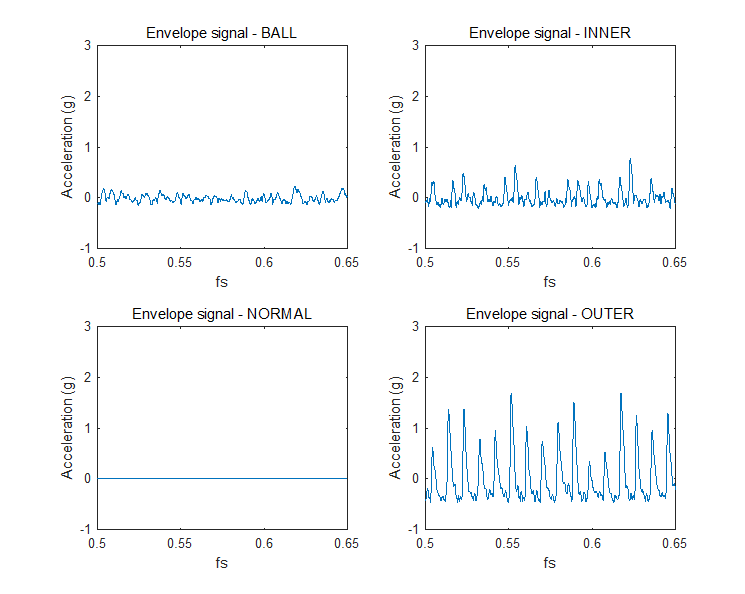

The reason for comparing the envelope is that the impact signals generated by bearing or gear faults show specific frequency patterns in the frequency domain. Envelope analysis extracts the high-frequency components of the vibration signal and converts them into low-frequency signals to analyze the fault's frequency patterns. As a result, it allows for a clearer analysis of the characteristic frequencies generated at the faulty section.

The graph above represents the frequency patterns expressed through the envelope of the data from Ball, normal, inner race, and outer race. As can be seen from the chart, the outer race shows significantly different frequency patterns compared to the other data.

Through the detection of BPFO, BPFI, and BPFB frequencies using the envelope spectrum, I aimed to establish a correlation between the detected fault frequencies and the faulty area of the bearing.

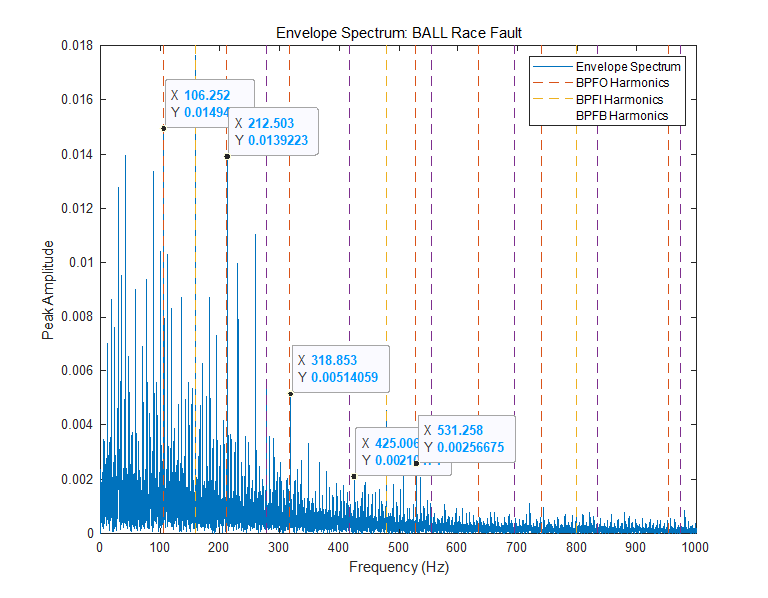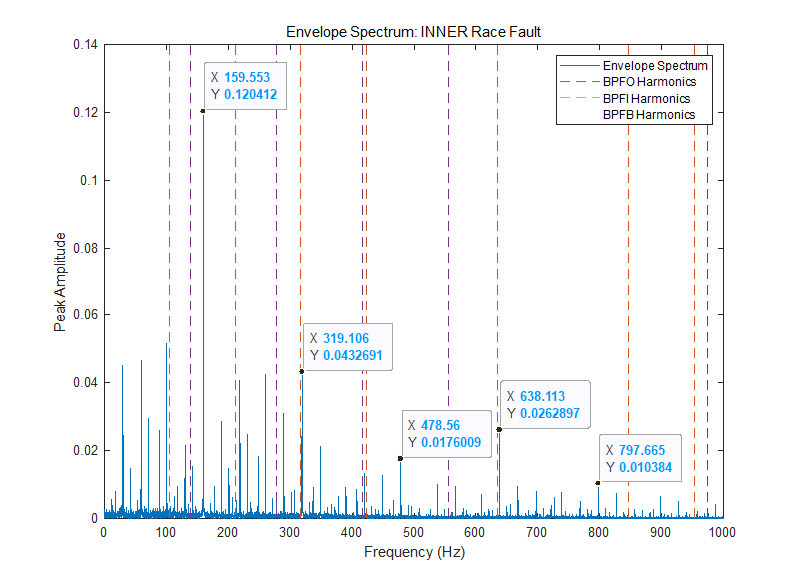

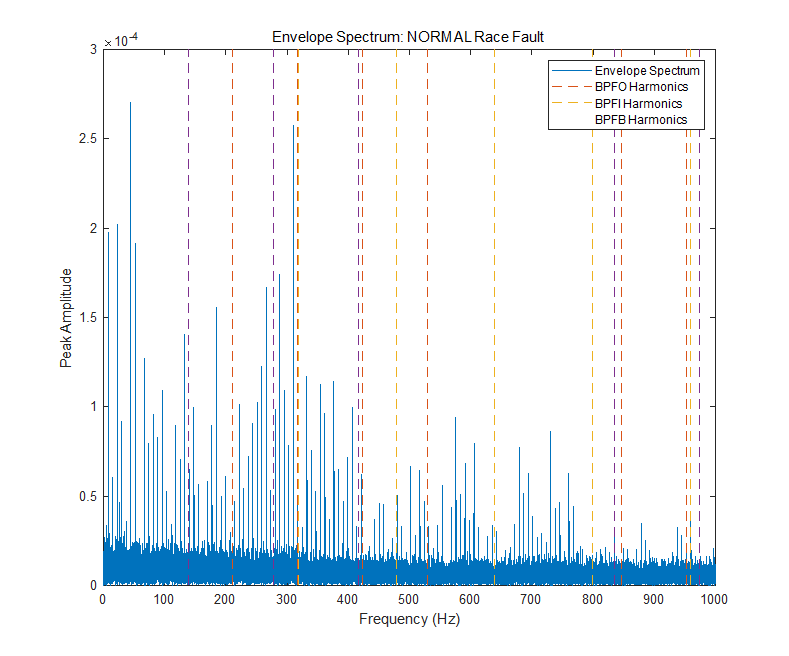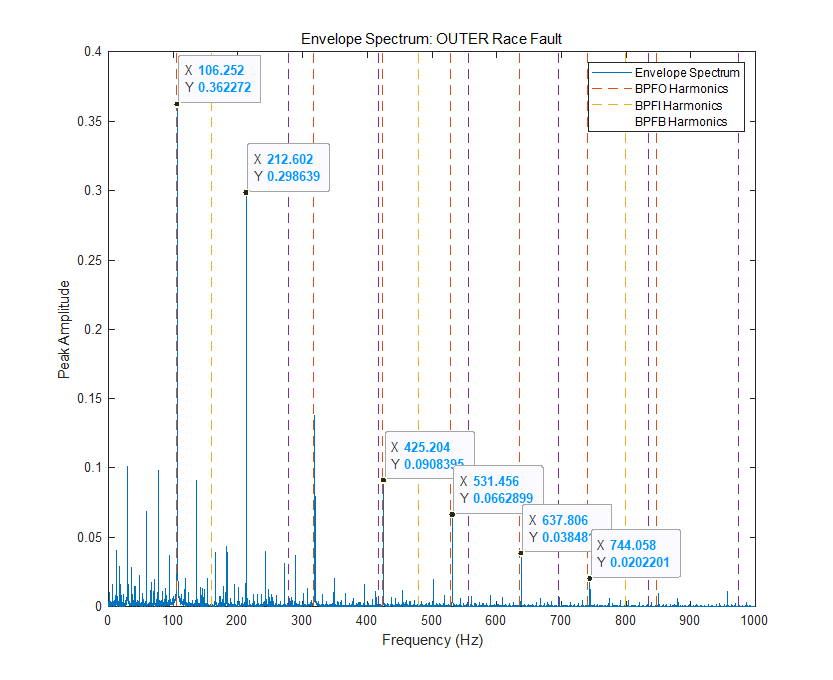

From the graph, it can be observed that, except for the normal data, there is a correlation with BPFI harmonics and BPFO harmonics.

### **7-4. Discussion about STFT**

STFT (Short-Time Fourier Transform) is an analysis technique that visually shows how a signal changes over time and which frequency components are present at specific moments. Additionally, a 2D spectrogram is plotted to compare the frequencies at specific times.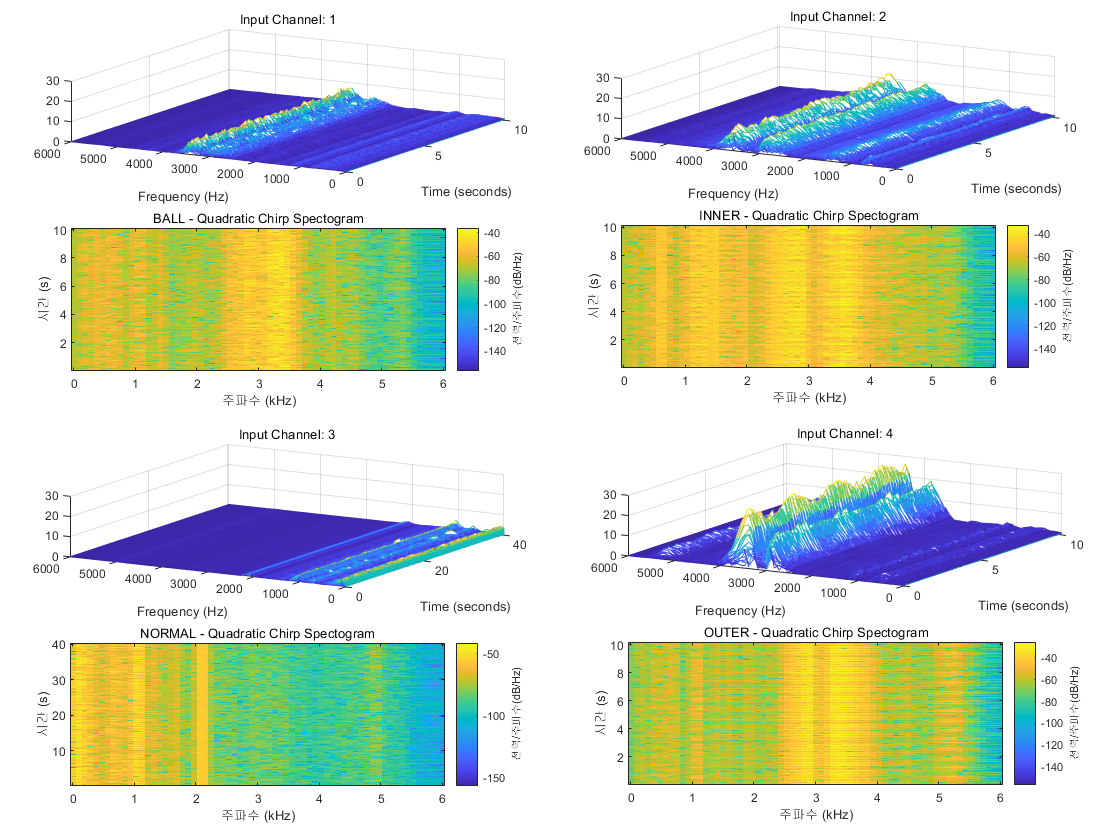

As can be seen from the graph, the Normal data shows little frequency variation, whereas the Ball, Inner, and Outer data exhibit significant frequency changes between 2000 Hz and 4000 Hz.

### **7-5. Discussion about Kurtogram**

The reason for analyzing Kurtosis is that the Kurtogram analyzes impact events or fault signals within the signal across different frequency bands, clearly showing where the fault has occurred. By using the Kurtogram to find the level at which each data set shows the optimal frequency resolution, it becomes possible to reduce the bandwidth and focus on analyzing the area where the fault is present. The table below shows the Kurtogram for each data set.

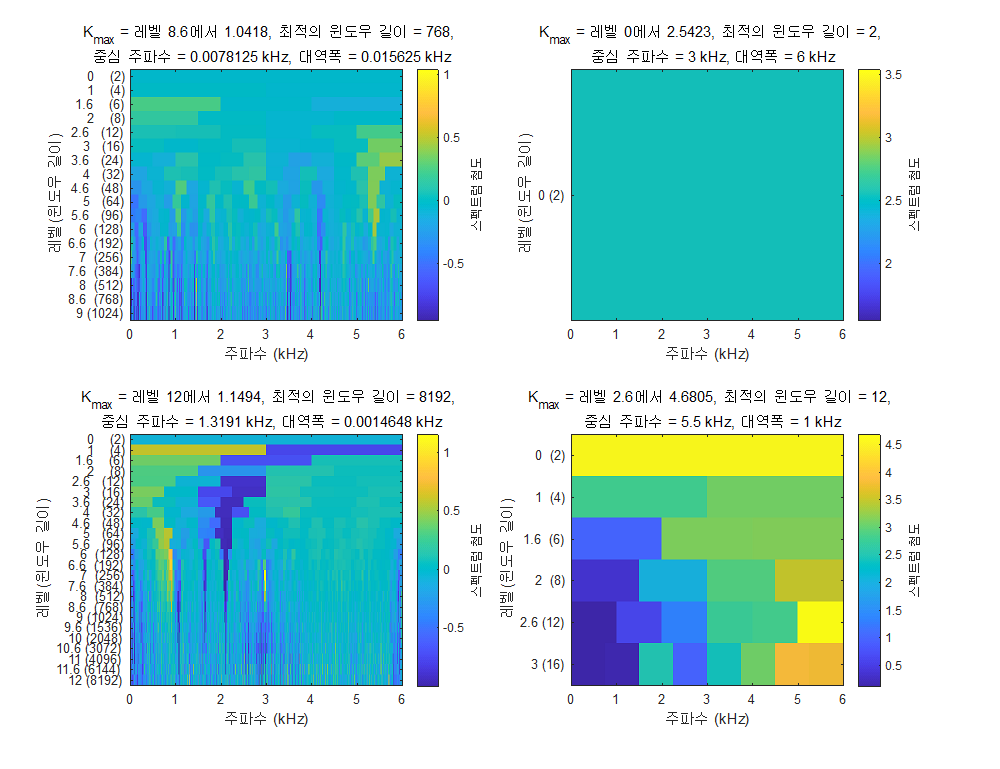

The following table compares the Spectral Kurtosis calculated with the Default Window Size and Default Level, and the Spectral Kurtosis calculated with the optimized Window Size and Level found using the earlier Kurtogram.

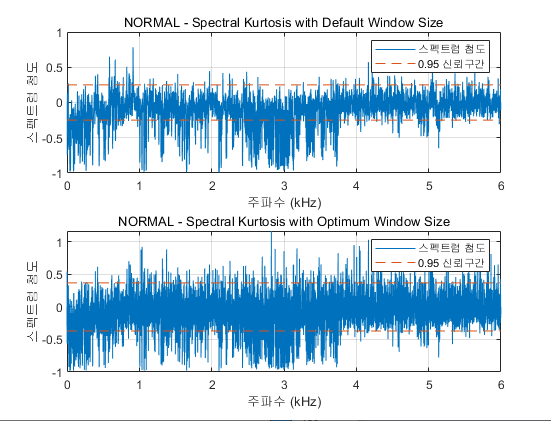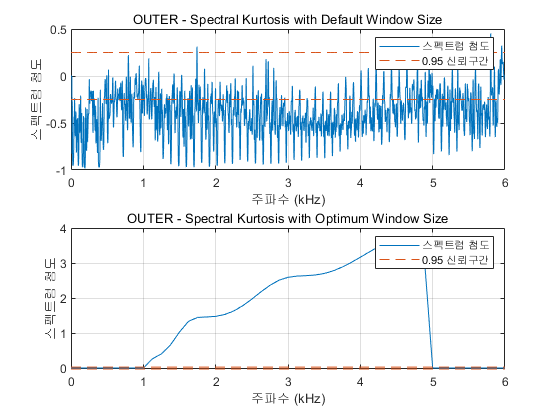

For the Normal Data in the upper graph, it is confirmed that the Spectral Kurtosis graph shows higher resolution with the optimized Window Size and Level than before. It is observed that most of the frequency components in the Normal Data are within the 0.95 confidence interval, while for the Outer Data, many components fall outside the confidence interval.

### **7-6. Discussion about Bandpass filter & Spectral Kurtosis**

By going beyond diagnosing bearing faults using the Kurtogram, the application of a Bandpass filter, which blocks low and high frequencies and allows only a specified frequency band to pass, made fault signals or impact signals in certain frequency ranges clearer.

T = table(kurtBALL, kurtBALLBpf, kurtINNER, kurtINNERBpf, kurtNORMAL, kurtNORMALBpf, kurtOUTER, kurtOUTERBpf);
disp(T);

    kurtBALL    kurtBALLBpf    kurtINNER    kurtINNERBpf    kurtNORMAL    kurtNORMALBpf    kurtOUTER    kurtOUTERBpf
    ________    ___________    _________    ____________    __________    _____________    _________    ____________

     2.9638       4.8767        5.5423         5.5462         2.9306         2.8441          7.595         8.7827   



As shown in the table, the Kurtosis values increased for the Ball Data, Inner race Data, and Outer race Data after applying the Bandpass filter, whereas the Kurtosis value decreased for the Normal Data.

This indicates that when a bearing has a fault, the Kurtosis value increases after applying the Bandpass filter, as observed through the analysis.

## 8. Conclusion

- Efforts were made to find a highly reliable fault verification method by analyzing the trends of data changes in both the Time Domain and Frequency Domain. While fault prediction for bearings could be easily performed through Time Domain Feature Extraction, it was insufficient to pinpoint which part of the bearing—Ball, Inner race, or Outer race—was faulty.

- The envelope process has the advantage of analyzing frequency change patterns while extracting high-frequency components. Although it was possible to find a match by comparing Envelope Data with BPFO, BPFI, and BPFB, the reliability in fault diagnosis remained low.

- Through STFT and the Kurtogram, the frequency range where the fault was visually predicted could be identified, and by applying the optimal window size and level in the Kurtogram, the frequency resolution improved, aiding in fault diagnosis. Subsequently, to enhance reliability in fault detection, a Bandpass filter was applied, which clarified the fault signals in specific frequency bands. After passing through the Bandpass filter, the Ball, Inner race, and Outer race fault data showed increased Kurtosis, indicating a rise in outlier values.

- Thus, while Feature Extraction methods can aid in fault diagnosis, in order to establish a clear threshold between fault and normal conditions, and to identify the specific faulty component, introducing machine learning techniques could help implement a more reliable fault diagnosis algorithm.